## Lab 4

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

The aim of this lab is to estimate the background from simulated data given to us. The data in Problem 1 is from a gamma-ray satellite and the data in Problem 2 are telescope images.

### Problem 1

We first import the hdf5 file and look at its structure. We are told that the data comes from a gamma-ray satellite in low Earth orbit, which takes a reading of the count of gamma-rays it detects in each 100 ms interval.

clear all; close all; clc
% Import data
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);
% Reset GPS time
mydata(:,1) = mydata(:,1)-940680015;

The file has 4 columns: time (GPS seconds), solar phase (deg), Earth longitude (deg), and particle counts. Initial plots of counts against time, solar phase and Earth longitude yielded little information as the plots were too dense. We are told that the satellite orbits Earth every 90 minutes and deduce that there might be a periodic pattern to the data. We therefore make a plot of counts against time over a 90-minute interval. 

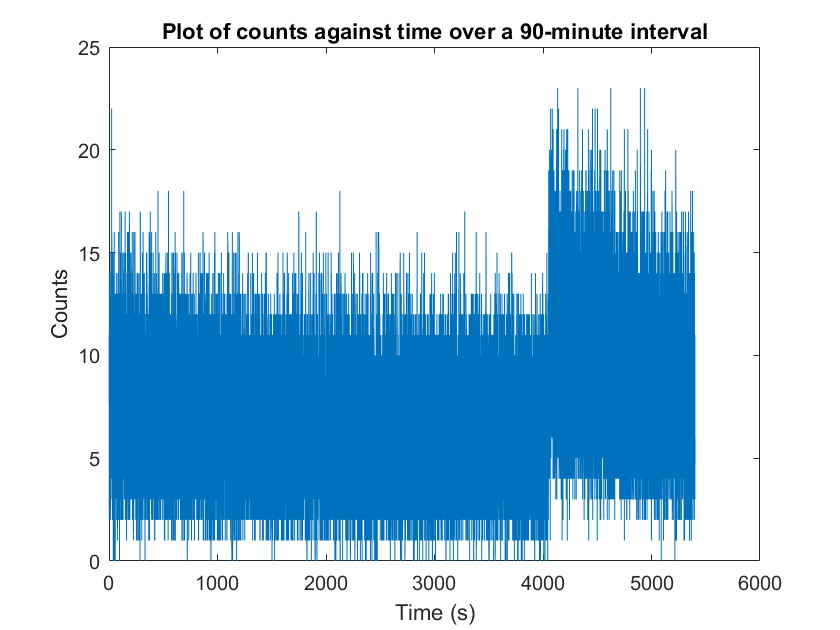

plot(mydata(1:54000,1),mydata(1:54000,4))
title('Plot of counts against time over a 90-minute interval')
xlabel('Time (s)')
ylabel('Counts')

The plot looks like it does have time dependence but the data points are still too dense to make out what we are looking at. To improve clarity, we reduce the number of data points by averaging every 100 rows in the data set. This means that we have 10 second averages of gamma-ray counts.

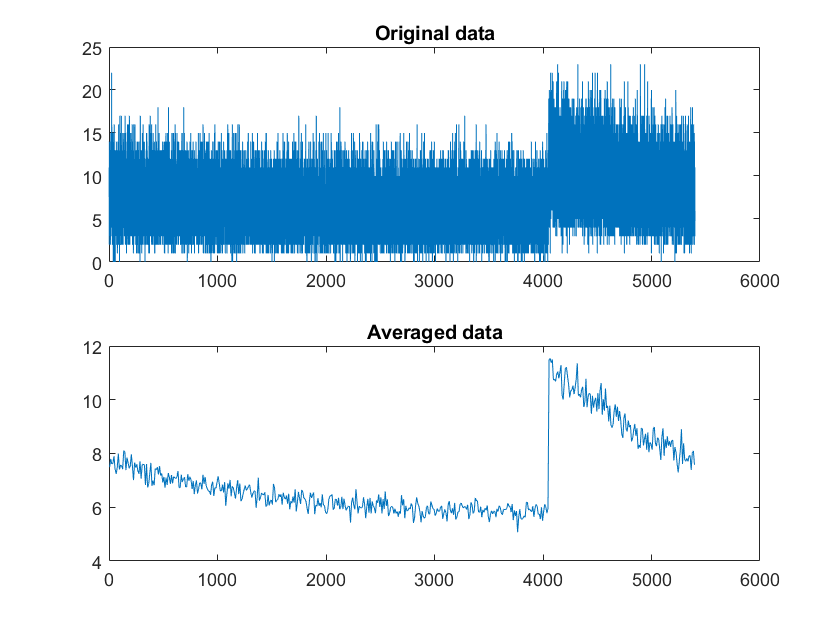

% Average in blocks of 100
rows = int64(length(mydata));
block = int64(100);
avgdata = zeros(idivide(rows,block),4);
count = 1;
mult = 0;
while count<=length(avgdata)
    start = mult*block;
    avgdata(count,:) = mean(mydata(start+1:start+block,:));
    count = count + 1;
    mult = mult + 1;
end
figure
subplot(2,1,1)
plot(mydata(1:54000,1),mydata(1:54000,4))
title('Original data')
subplot(2,1,2)
plot(avgdata(1:540,1),avgdata(1:540,4))
title('Averaged data')

The time dependence of gamma-ray counts is much clearer once we average the data. To identify if the time dependence is periodic, we need to plot the counts over a longer time period.

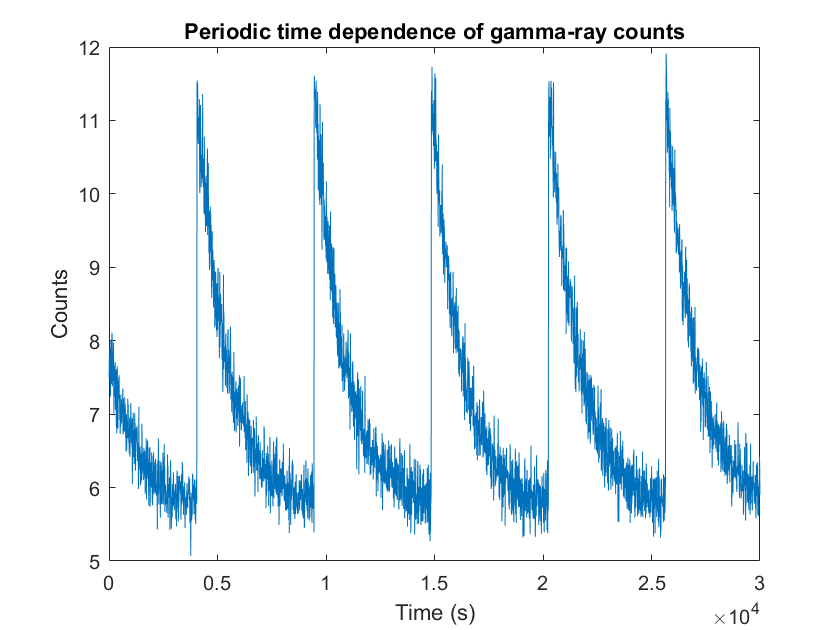

% Look at a longer time span
figure
plot(avgdata(1:3000,1),avgdata(1:3000,4))
xlabel('Time (s)')
ylabel('Counts')
title('Periodic time dependence of gamma-ray counts')

The data does look like it has periodic time dependence. It jumps approximately every 5000 seconds and looks like it exponentially decays after that.

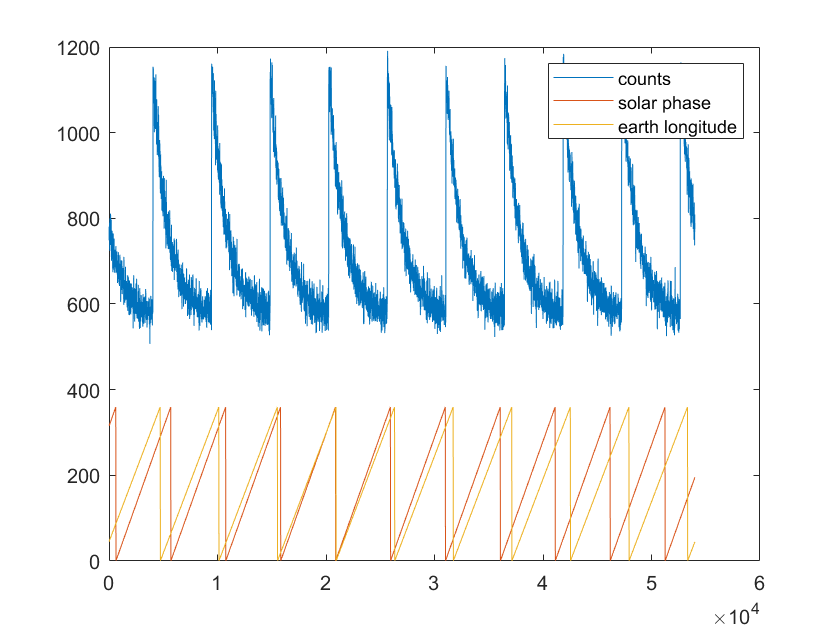

plot(avgdata(1:5400,1),100*avgdata(1:5400,4))
hold on
plot(avgdata(1:5400,1),avgdata(1:5400,2))
plot(avgdata(1:5400,1),avgdata(1:5400,3))
legend('counts','solar phase','earth longitude')
hold off

At this point, we are still concerned with what the data looks like from a high level. One worry we have is the aging of the detector - it could have gotten less sensitive as time passed. To test this, we sum all the counts in a single period such that we get a sum for each period, and compare these sums to see if they decrease over time. We take this approach because reduced sensitivity would affect counts throughout the period, and if the sensitivity does decrease, we would see fewer total counts per period during later periods.

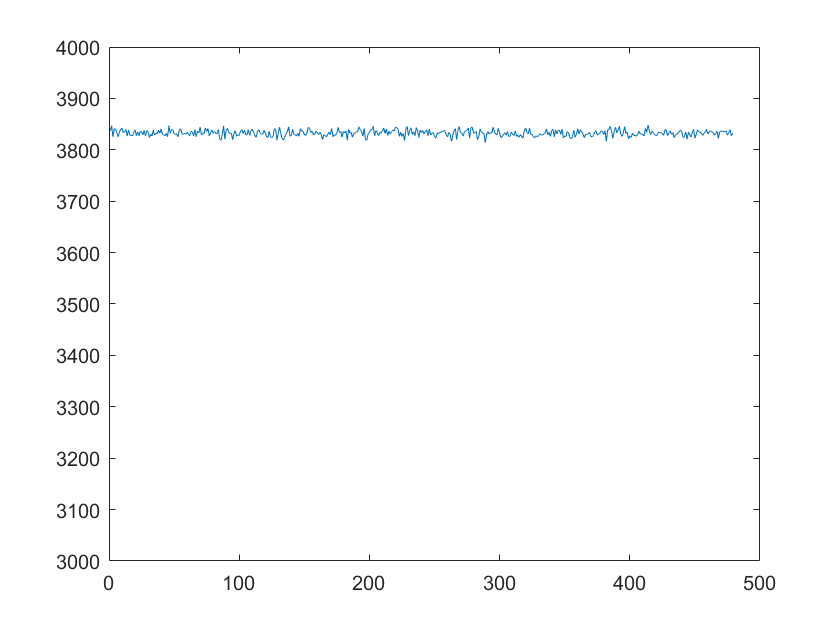

% Define boundaries of periods
% if current value is at least 2.5 greater than last value
% current value is start of next period
% store current sum
% start new sum
sumcount = avgdata(1,4);
psum = [];
split = [];
for jj=2:length(avgdata)
    temp = avgdata(jj,4);
    if temp-avgdata(jj-1,4)>3
        % store current sum
        psum = [psum;sumcount];
        sumcount = temp;
        split = [split;jj];
    else
        sumcount = sumcount+temp;
    end
end
plot(psum(2:end))
ylim([3000 4000])

Just from eyeballing the plot, it looks like the sum stays constant through time. There is no noticeable trend that would indicate a decay over time. As such, we may consider the aging of the detector to have a negligible effect on the counts.

We were also interested to see how the counts change with the solar phase and Earth longitude. 

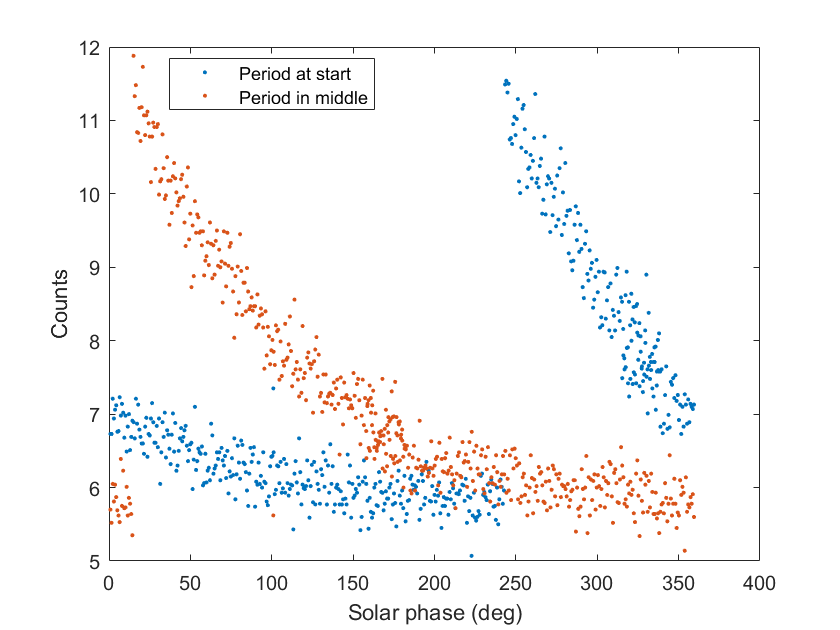

plot(avgdata(1:540,2),avgdata(1:540,4),'.')
hold on
plot(avgdata(100001:100540,2),avgdata(100001:100540,4),'.')
ylabel('Counts')
xlabel('Solar phase (deg)')
legend('Period at start','Period in middle','Location','best')
hold off

An initial plot of counts against solar phase shows a shift of the data between the start of the data set and the middle, so we explore this dependence more.

We made an animation in Appendix A showing the gamma-ray counts to see if there are any irregularities in the data over time. Below is a snapshot of the animation.

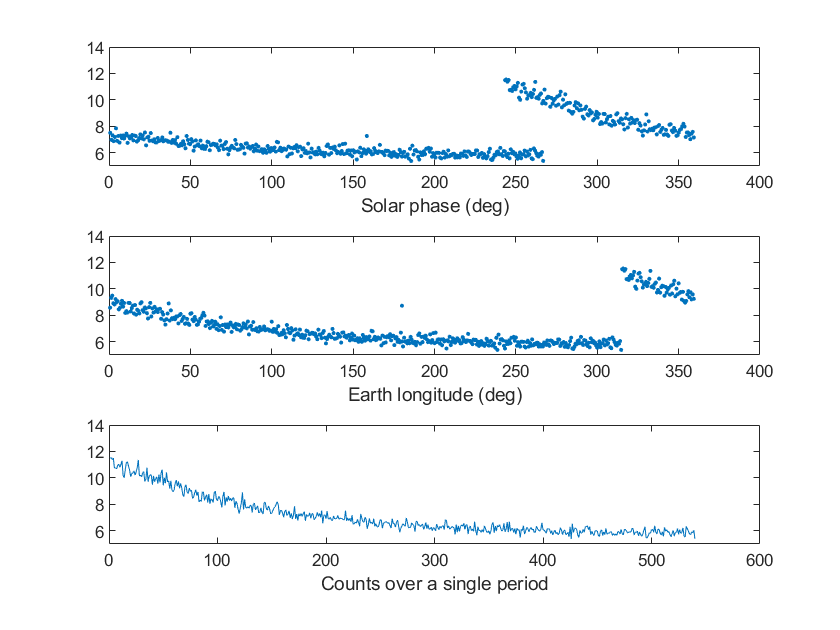

pstart = split(1);
pend = split(2)-1;
% Make plots
subplot(3,1,1)
plot(avgdata(pstart:pend,2),avgdata(pstart:pend,4),'.')
ylim([5 14])
xlabel('Solar phase (deg)')
subplot(3,1,2)
plot(avgdata(pstart:pend,3),avgdata(pstart:pend,4),'.')
ylim([5 14])
xlabel('Earth longitude (deg)')
subplot(3,1,3)
plot(avgdata(pstart:pend,4))
ylim([5 14])
xlabel('Counts over a single period')

Each frame shows data in the same period plotted on three different axes. The animation shows the data sweeping across the solar phase axis over time, while staying approximately constant on the earth longitude axis. The movement across the solar phase axis arises because as the satellite orbits Earth, Earth is also turning. When the satellite reaches its original starting point above the Earth, that point on the Earth is now facing a different direction relative to the sun. This causes an overlap on the solar phase axis (multiple data values collected for the same solar phase), and an offset that causes the data to shift along the solar phase axis every period.

It is interesting that there is a hard jump on the Earth longitude axis at exactly 315 degrees every period. I do not know what causes this.

Constructing the background

Now that we have an idea of how the data behaves and some of its features, we begin to construct a model for our background distribution. The background periodically changes (decays) over time, so we consider constructing a background for a single period and treat each period as a trial.

The data collection process exhibits features of a Poisson distribution: discrete counts over a time interval.

The following steps are taken to construct the background distribution:

1. Consider the first time point in each period. Put each data point in a histogram.

2. Use Matlab's poissfit function to fit these data points to a Poisson distribution.

3. Convolve this Poisson fit 100 times to average it, and overlay it on the histogram to see how well it fits the data.

4. Find the 5-sigma value of the resulting distribution.

5. Repeat for subsequent time points.

Step 3 was discovered by trial and error. An unaveraged Poisson distribution was too wide when overlayed with the data, so I deduced that it had to be averaged to reduce the width of the distribution. Finding the number of times to convolve it took some time. I initially thought that convolving it 480 times made the most sense since there were 480 trials (ie. 480 periods), but this resulted in too narrow a distribution. The distribution fit the data well when it was convolved 80 times, but there was nothing in my procedure to suggest why this would be the case. At this point, I recalled that I had initially reduced my data set by taking averages of 100-row blocks. Therefore, each data point in the histogram was an average over 100 time points, which is why it made sense to me that convolving the Poisson fit 100 times would give me a fitted distribution to the histogram.

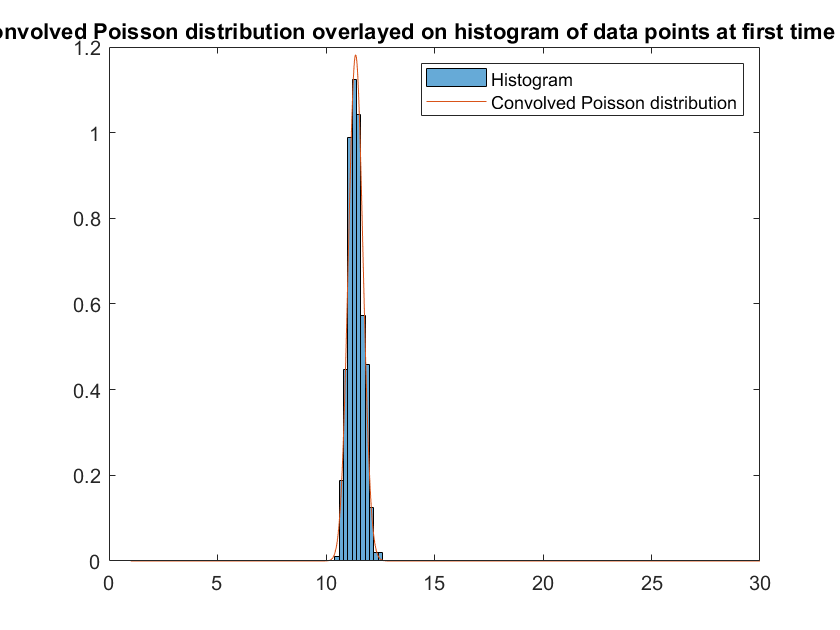

% Make histogram
figure
data1 = avgdata(split,4);
mu = poissfit(data1);
histogram(data1,'Normalization','pdf')
hold on
x = [1:30];
% plot(480*poisspdf(x,mu))
% convolve it 100 times because that is the block size used
convolved = poisspdf(x,mu);
for jj=1:99
    convolved = conv(poisspdf(x,mu),convolved);
end
x1 = [1:1/100:30];
plot(x1,100*convolved)
hold off
title(['Convolved Poisson distribution overlayed on histogram of data ' ...
    'points at first time point'])
legend('Histogram','Convolved Poisson distribution')

The plot above compares the data with our modelled background distribution for the first time point in each period. We are interested in finding the 5-sigma value of the modelled background distribution.

tempsum = 0;
count = 0;
a = normcdf(5,'upper');
while tempsum<a
    tempsum = tempsum + convolved(end-count);
    count = count+1;
end
xval = x1(end-count+1);

For the first time point (let us call it $t_1$), the 5-sigma value is 13.1. We repeat the procedure for subsequent time points to find the time dependence of the 5-sigma value. We only do this every 10 time points to save time on computations. The results should give us an idea of the 5-sigma time dependence without significant error.

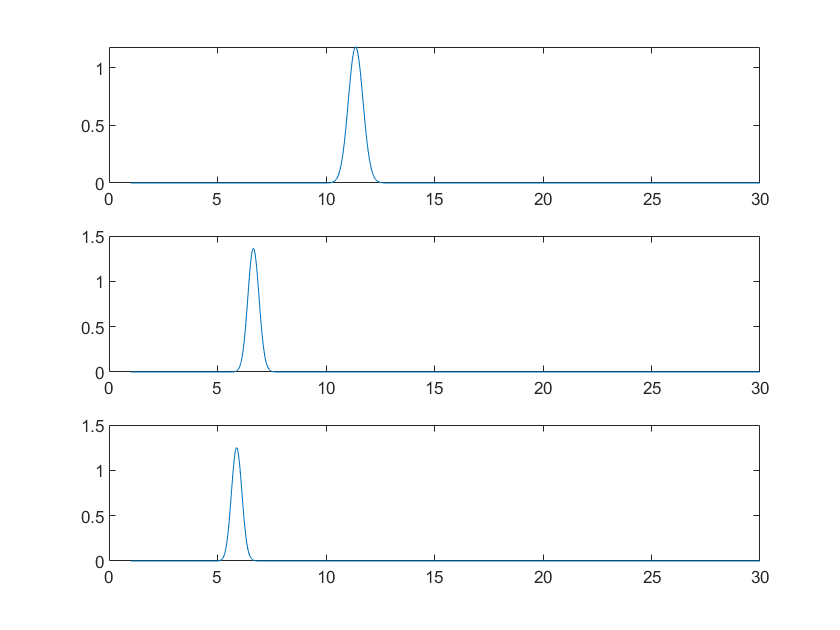

% Write loop for each time point t1 to t531

bmodel = zeros(length(x1),54);
tsig = zeros(1,54);
for t = [0:10:530]
    %figure
    datat = avgdata(split(1:end-1)+t,4);
    mu = poissfit(datat);
    x = [1:30];
    % convolve it 100 times because that is the block size used
    convolved = poisspdf(x,mu);
    for jj=1:99
        convolved = conv(poisspdf(x,mu),convolved);
    end
    tempsum = 0;
    count = 0;
    while tempsum<a
        tempsum = tempsum + convolved(end-count);
        count = count+1;
    end
    tsig(t/10+1) = x1(end-count+1);
    bmodel(:,t/10+1) = 100*convolved;
end
figure
subplot(3,1,1)
plot(x1,bmodel(:,1))
subplot(3,1,2)
plot(x1,bmodel(:,25))
subplot(3,1,3)
plot(x1,bmodel(:,50))

The plots show the background distribution at the start, in the middle, and at the end of the period. It gets narrower as the period progresses, indicating that the data gets less spread out.

The plot below shows how the 5-sigma threshold changes over a period. As expected, it decreases in the same manner that the data decays.

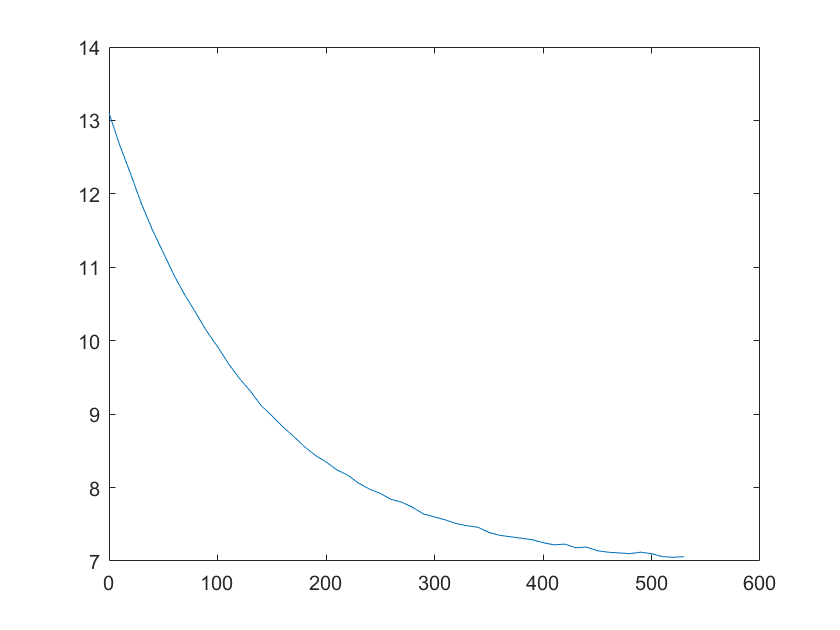

figure
plot([0:10:530],tsig)

### Problem 2

    We are given simulated data in the form of stack of 10 200 x 200 pixel images from a telescope. Our goal is to look for the faintest stars in the images.

We begin by exploring the data. Initial plots show a 'night sky' with what look like stars.

h5disp("images.h5")

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


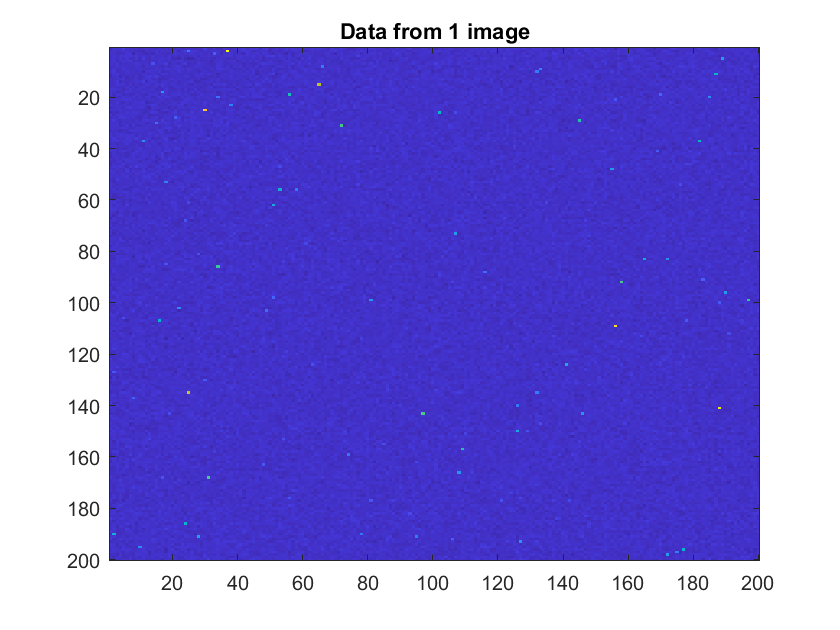

img1 = h5read("images.h5",'/image1');
imagesc(img1)
title('Data from 1 image')

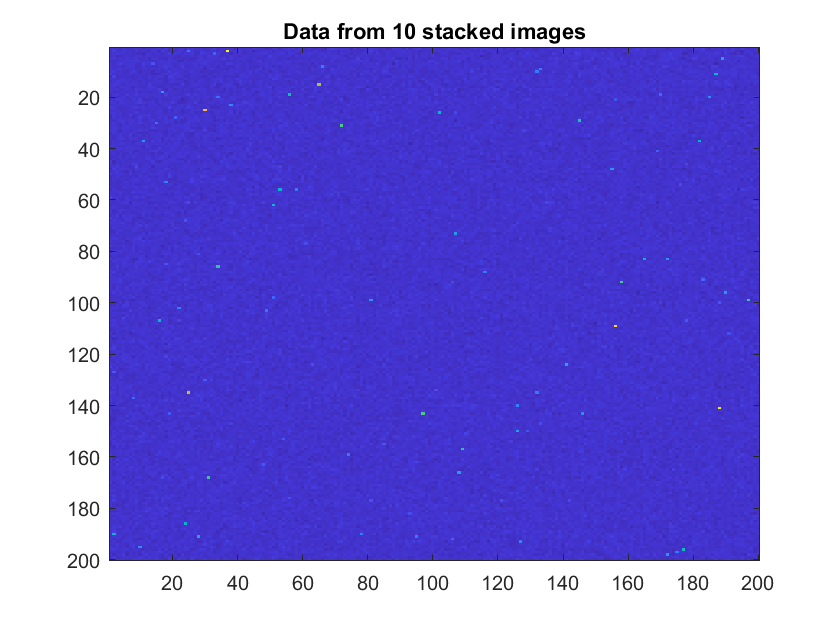

imgall = h5read("images.h5",'/imagestack');
imgall = permute(imgall,[2 3 1]);
figure
for jj = 1:10
    imagesc(imgall(:,:,jj))
    hold on
end
title('Data from 10 stacked images')
hold off

When plotted on a 3D graph, we see spikes that indicate higher values, which may be stars. For clarity, we zoom in on a 50 x 50 pixel region of the image.

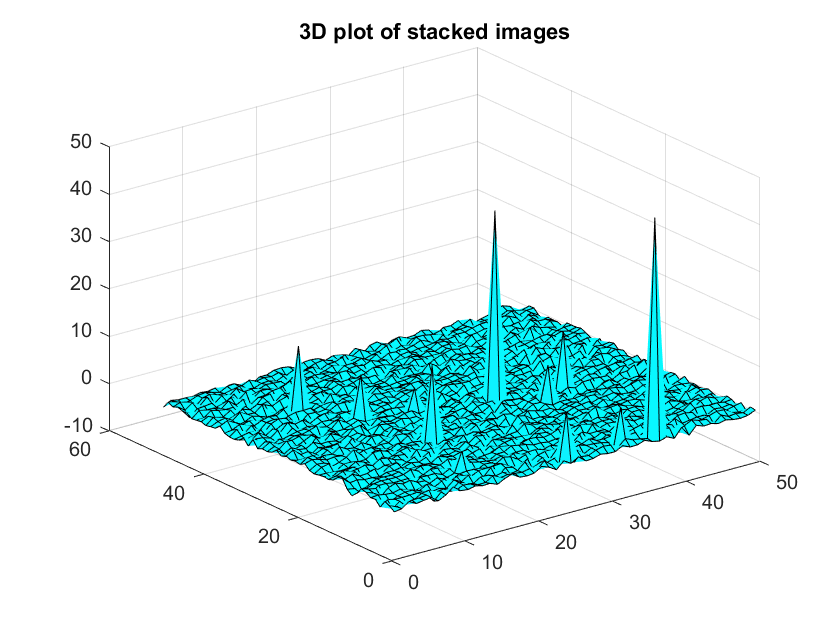

surf(imgall(1:50,1:50,1))
title('3D plot of stacked images')
colormap(cool)

There is signal contamination in the data. We are looking for stars, but stars are present in the data we are given. To deal with this, we difference images to negate the presence of stars (a star in one image is likely to be present in another). For example, the plot below shows the difference between the first and second images.

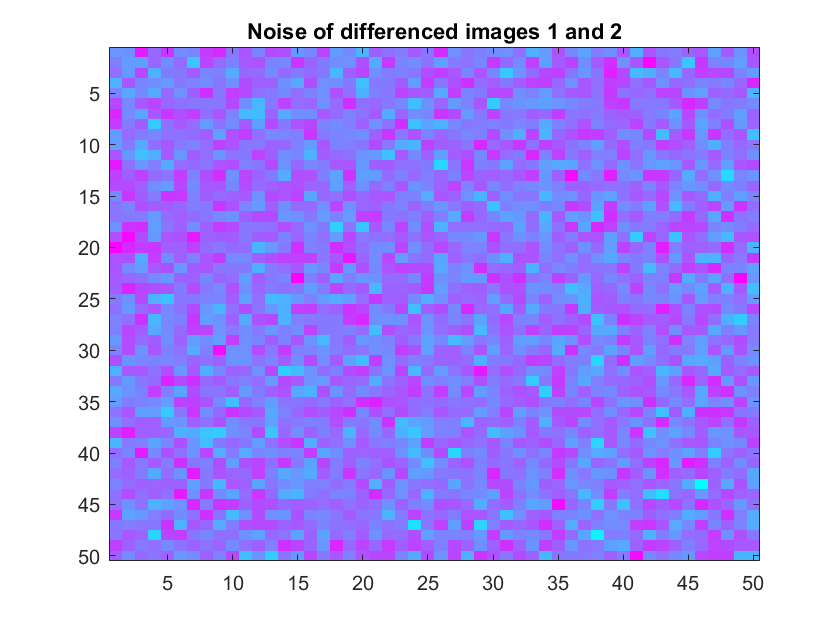

imagesc(imgall(1:50,1:50,1)-imgall(1:50,1:50,2))
title('Noise of differenced images 1 and 2')

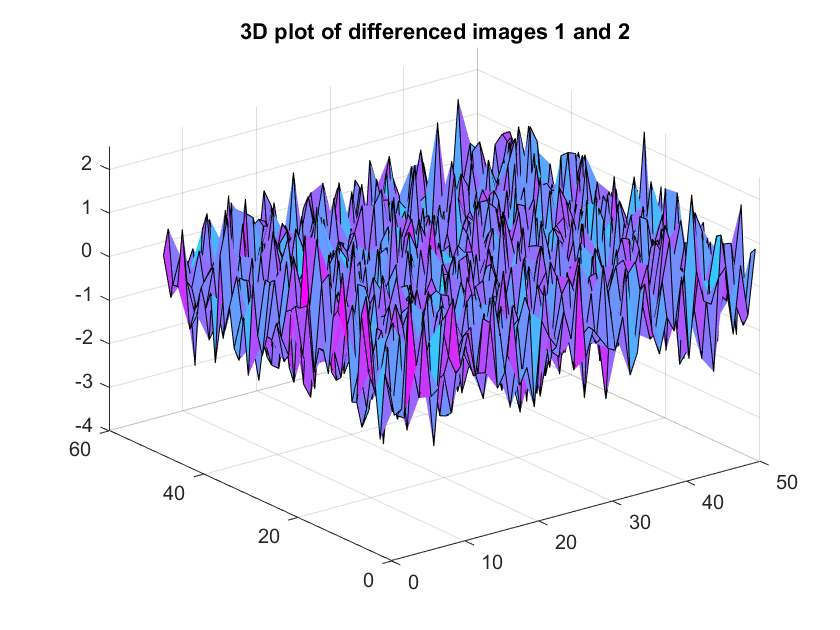

surf(imgall(1:50,1:50,1)-imgall(1:50,1:50,2))
title('3D plot of differenced images 1 and 2')

This is promising. Deviations are slight with respect to the magnitude of spikes, and resemble an empty night sky. We plot a histogram of the deviations below.

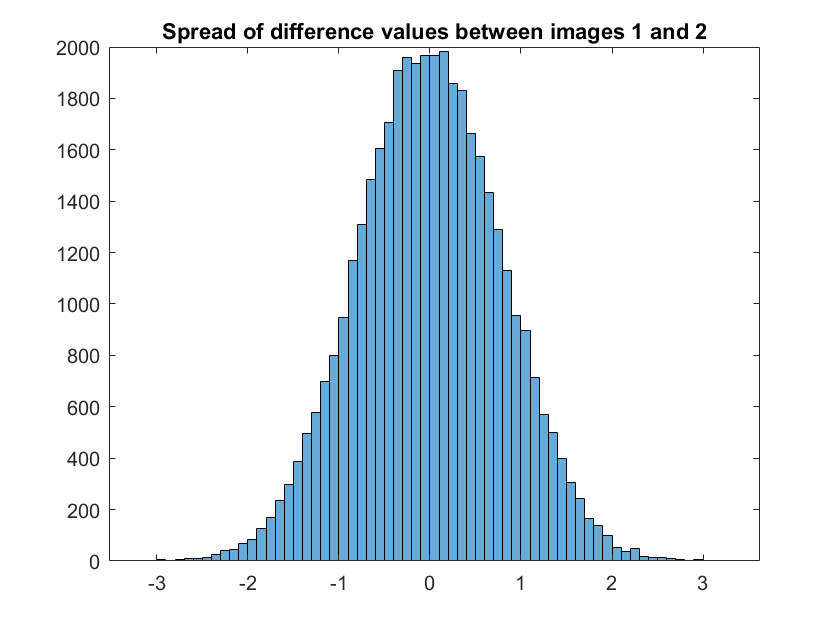

diff12a = imgall(:,:,1)-imgall(:,:,2);
diff12 = reshape(diff12a,[],1);
histogram(diff12)
title('Spread of difference values between images 1 and 2')

The plot resembles a Gaussian distribution. Fitting this data to a Gaussian distribution and plotting it over the normalized histogram yields the following plot:

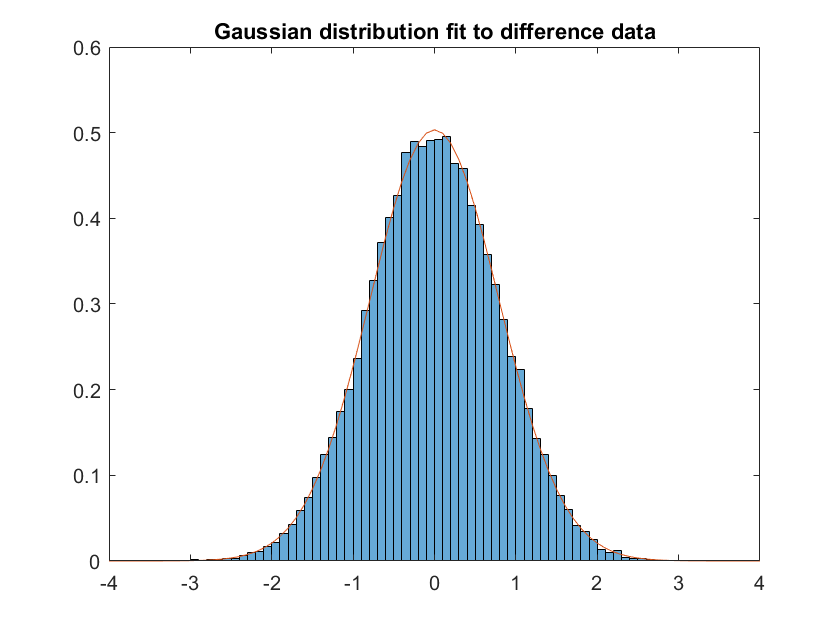

[mu12,sig12] = normfit(diff12);
x12 = -4:0.1:4;
figure
histogram(diff12,'Normalization','pdf')
hold on
plot(x12,normpdf(x12,mu12,sig12))
title('Gaussian distribution fit to difference data')

We can repeat this procedure for every possible difference between images, and then average the difference by convolving all the distributions. This gives us an estimate of the background distribution based on all the images.

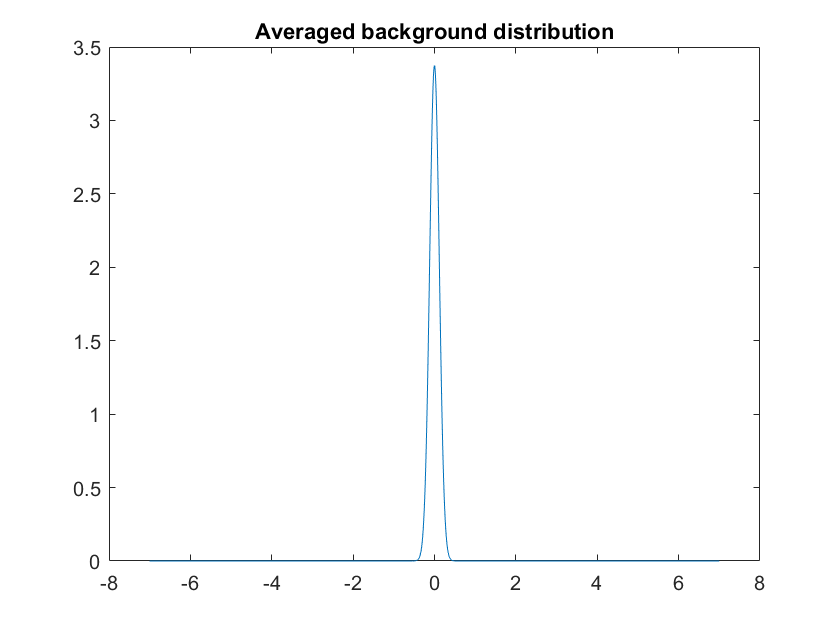

xrange = -7:0.1:7;
difffit = zeros(45,2);
count = 0;
for jj=1:9
    for kk=jj+1:10
        count = count+1;
        diffb = imgall(:,:,jj)-imgall(:,:,kk);
        diffb = reshape(diffb,[],1);
        [mutemp,sigtemp] = normfit(diffb);
        difffit(count,:) = [mutemp sigtemp];
    end
end

% convolve distributions
conv2 = normpdf(xrange,mu12,sig12);
for jj=2:length(difffit)
    mufit = difffit(jj,1);
    sigfit = difffit(jj,2);
    temp = normpdf(xrange,mufit,sigfit);
    conv2 = conv(temp,conv2);
    conv2 = conv2/(0.1*sum(conv2));
end
x2 = -7:0.1/length(difffit):7;
conv2 = length(difffit)*conv2;
figure
plot(x2,conv2)
title('Averaged background distribution')

The plot above shows the averaged background distribution. We can integrate the upper tail to find the 5-sigma value.

tempsum = 0;
count = 0;
a = normcdf(5,'upper');
while tempsum<a
    tempsum = tempsum + conv2(end-count);
    count = count+1;
end
sig2 = x2(end-count+1);
disp(table(sig2,'VariableNames',{'5 sigma threshold'}))

    5 sigma threshold
    _________________

         0.71778     



Now that we have determined our 5-sigma threshold, we can consider any value above this threshold to be a star.

Hunt for faint stars

We look for all stars in an image by iterating through all elements of the array, and amplifying any value greater than the 5-sigma threshold. We only want the upper tail because stars would give off light, so a higher value is considered more signal-like.

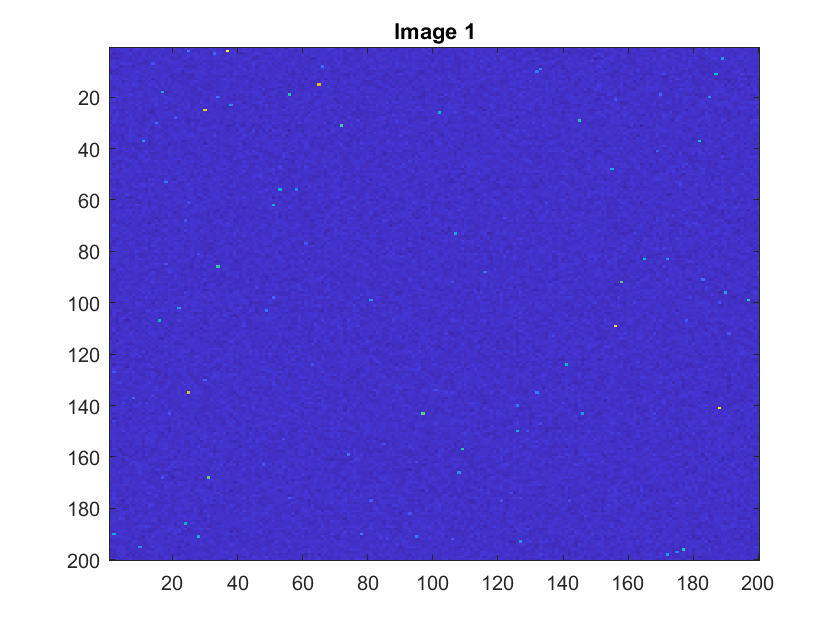

% Look through all pixels in an image
% if pixel has value > 0.71778
% Amplify it
A = imgall(:,:,1)>sig2;
figure
imagesc(imgall(:,:,1))
title('Image 1')

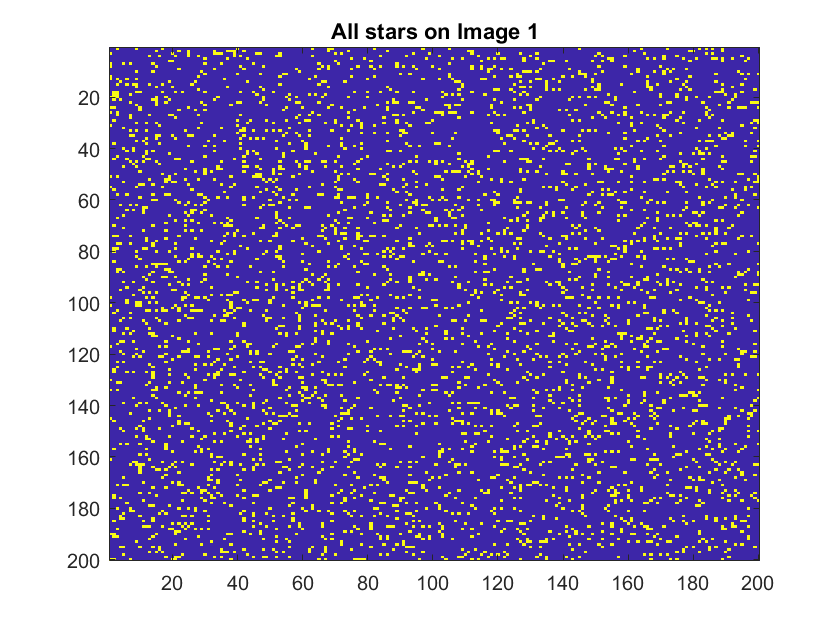

figure
imagesc(A)
title('All stars on Image 1')

The images above compare the original image with an amplified image. All the stars stand out in yellow based on our search using the 5-sigma threshold. Not all the images have stars in the same region, however. The image below shows the difference between images 1 and 2, with yellow pixels stars on image 1 and blue pixels stars on image 2.

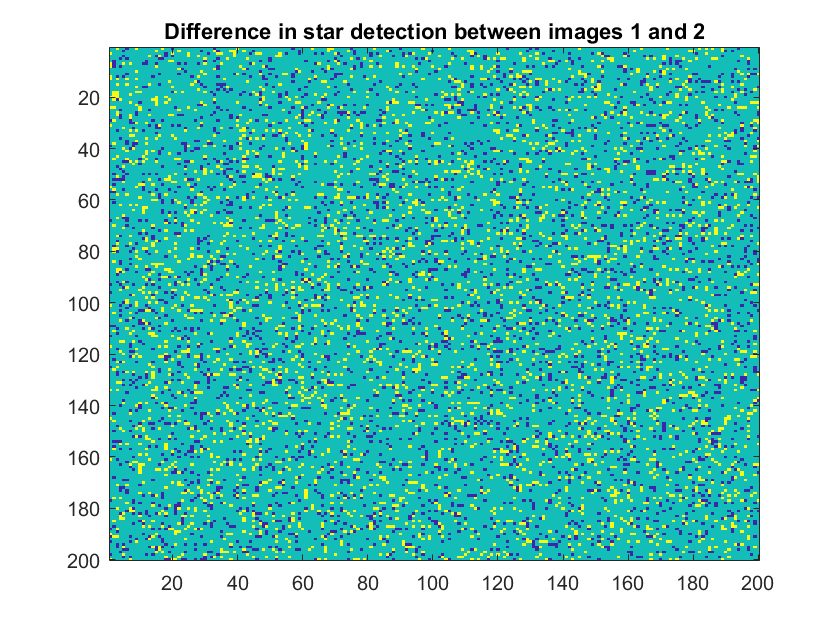

B = imgall(:,:,2)>sig2;
figure
imagesc(A-B)
title('Difference in star detection between images 1 and 2')

### Appendix A

Animation of gamma-ray counts on different axes. Only works on Matlab.

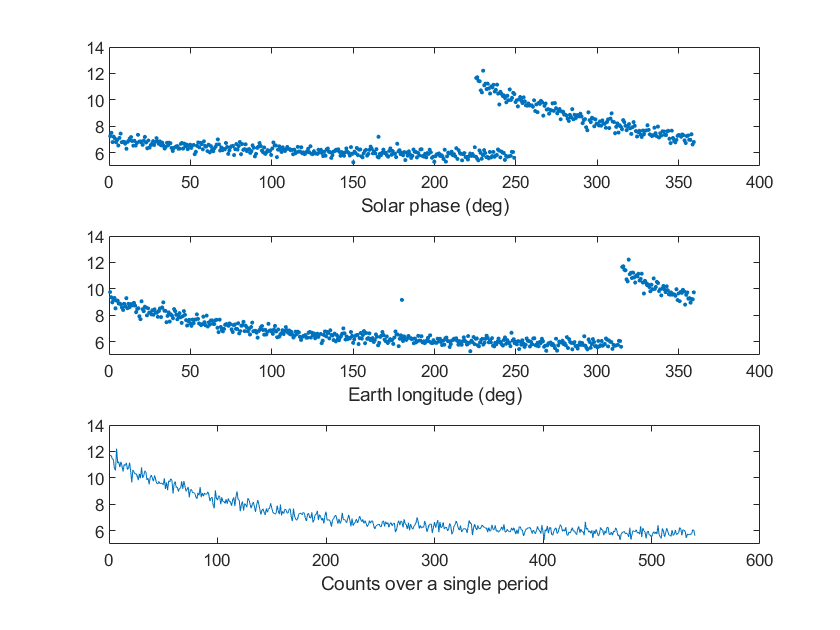

% get plot range from split
figure
for jj=1:length(split)-1
    pstart = split(jj);
    pend = split(jj+1)-1;
    % Make plots
    subplot(3,1,1)
    plot(avgdata(pstart:pend,2),avgdata(pstart:pend,4),'.')
    ylim([5 14])
    xlabel('Solar phase (deg)')
    subplot(3,1,2)
    plot(avgdata(pstart:pend,3),avgdata(pstart:pend,4),'.')
    ylim([5 14])
    xlabel('Earth longitude (deg)')
    subplot(3,1,3)
    plot(avgdata(pstart:pend,4))
    ylim([5 14])
    xlabel('Counts over a single period')
    pause(0.1)
end